# MATH2089 Lab 5

In the previos lab we had a brief look at *estimators*—a function of your sample data used to provide an informed estimate of an unknown quantity. These unknown quantities can be generally classed into two categories

- Model parameters: quantities that define the exact type of distribution, e.g., $\lambda$ in the $\text{Exp}(\lambda)$ distribution

- Population parameters: quantities that arise from distributions, e.g., the true population mean $\mu$ for a given distribution $F_{\theta}$

In some cases the model and population parameters coincide, e.g., the mean $\mu$ for the Normal distribution. Similarly to estimators, *sample statistics* are any function of only your sample data—not necessarily used to estimate a model parameter. For example, we might want to compute $T = n^{-1}\sum^{n}_{i = 1} \mathbf{1}\{X_{i} < c\}$—the proportion of a sample $X_{1},\dots,X_{n}$ that is smaller than $c$. The aforementioned statistic $T$ is usually not related to any model parameter, but does provide an estimate for the population parameter $F(c) = \mathbb{P}(X < c)$. Of course in some instances the sample statistic will also be an estimator, e.g., the sample mean is a sample statistic and an estimator for the population and model parameter $\mu$ for the $N(\mu, 1)$ distribution. Note that a statistic cannot include unknown quantities such as unknown model parameters.

In today's lab we'll use statistics to estimate the population mean and proportion—prefacing *population* implies that the quantity is with respect to the true data generating distribution $F$ and not the sample $X_{1},\dots,X_{n}$. As statistics are functions of random variables, the sample statistic is itself also a random variable, and hence has a distribution. The value of the statistic will depend on the sample we obtain, and so it can be overzealous to assume the population parameter is equal to the observe sample statistic. As an example, suppose that the population mean $\mu = 0$. 

rng(11) % set the seed to fix the random number generator

sampleOne = normrnd(0, 1, 5, 1)

sampleOne =    -0.4226
   -1.7742
   -0.0726
    1.1950
   -0.1232


sampleTwo = normrnd(0, 1, 5, 1)

sampleTwo =    -0.0306
   -2.4298
   -0.0565
    0.6516
    1.7254



mean(sampleOne)

ans = -0.2395

mean(sampleTwo)

ans = -0.0280

We see that neither of the sample averages is exactly 0, although the sample average from the second sample is certainly closer. In practice we don't know the value of the population parameter, so we can't determine how close our observed sample statistic is. However, if our sample statistic is unbiased—so that the expected value of the sample statistic is equal to the population paramter—then we can add some margin of error using the distributional properties of the sample statistic to give us a range of plausible values for the population parameter. 

## Exercise 1

In this question we want to estimate the population mean for `shearstrength`. Let's begin as usual by plotting the data. 

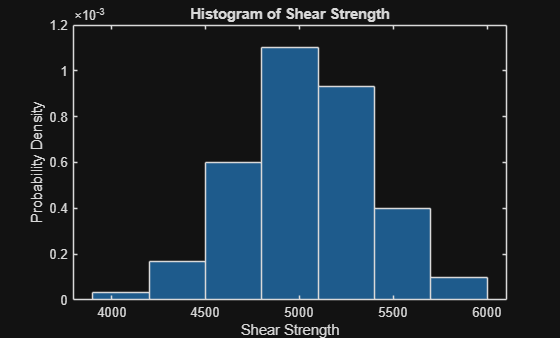

shearstrength = readvars("data\shearstrength.txt");

histogram(shearstrength, "Normalization", "pdf");
xlabel('Shear Strength');
ylabel('Probability Density');
title('Histogram of Shear Strength');

The histogram is bell-shaped, which gives us some indication that `shearstrength` may be Normally distributed. We can get a more precise depiction of the Normality of `shearstrength` through a quantile plot.

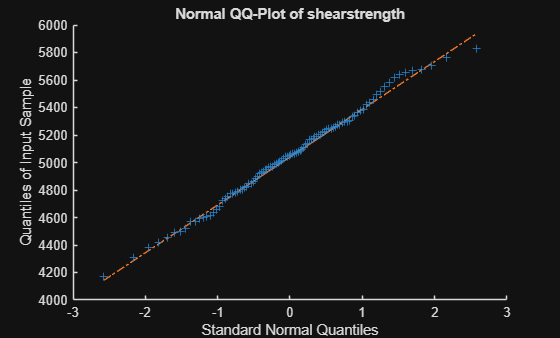

qqplot(shearstrength);
title("Normal QQ-Plot of shearstrength")

Here we can clearly see that the `shearstrength` is Normally distributed since the quantiles of the sample data align closely with the quantiles of a Normal distribution. Based on the quantile plot, we'll make the assumption that `shearstrength` is Normally distributed. In practice you are unlikely to see data sets align exactly with the quantile line—see the example of a precisely Normal data set below. When making an assessment, we try to establish whether the data is globally approximated by the Normal quantiles. You are likely to see some deviation in the tails as these points are inherently more variable.  

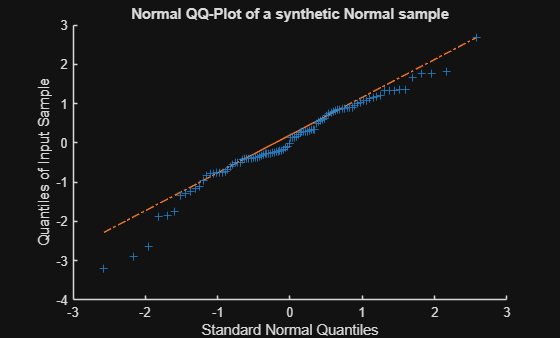

qqplot(normrnd(0, 1, 100, 1));
title("Normal QQ-Plot of a synthetic Normal sample")